NOMBRE:  **PABLO **

APELLIDOS: **MENDIETA RUIZ **

FECHA: **21 / 02 / 24**

## T2.E1A. Descarga de un tanque esférico

Estás diseñando un tanque esférico como el de la figura para almacenar agua para un poblado pequeño en un país en desarrollo. 

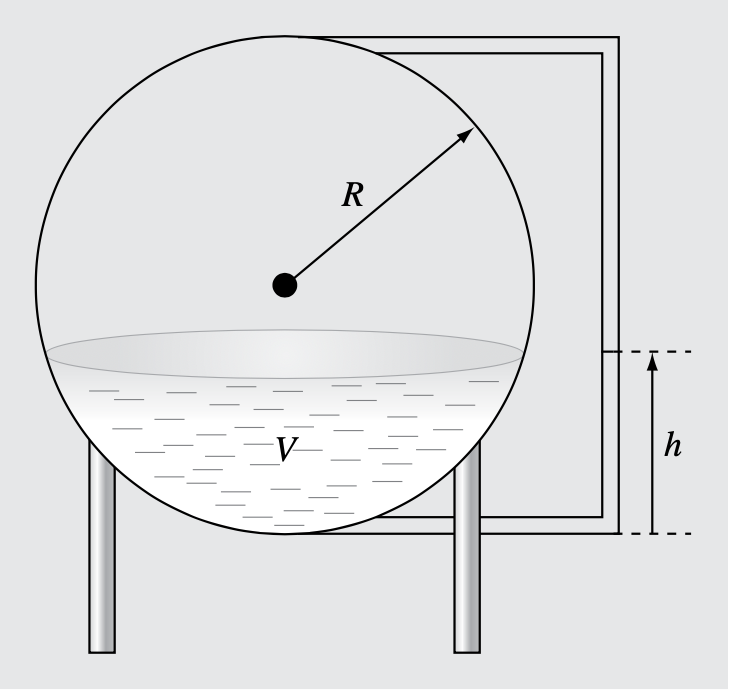

El volumen de líquido que puede contener se calcula mediante: $V=\pi h^2 \frac{\left(3R-h\right)}{3}$, donde:

$V=$ volumen en $m^3$

$h=$ profundidad del agua en el tanque en $m$

$R=$ radio del tanque en $m$

Si $R=3\;m$, se desea saber a qué profundidad debe llenarse el tanque de modo que contenga 30 $m^3$.

a) Rescribe la ecuación de modo que la raíz sea la solución buscada (mediante el editor de ecuaciones) $f\left(h\right)=0$

b) Dibuja la gráfica de la ecuación donde se aprecie claramente dónde se encuentra la raíz

c) Calcula la altura del agua en el depósito con un error menor que ${10}^{-6}$ mediante el método de la falsa posición. Indica el número de iteraciones empleadas. Verifica que el resultado es correcto calculando el volumen contenido en el depósito

### Respuesta

**a)**


$$V=\pi h^2 \frac{\left(3R-h\right)}{3}\to f\left(h\right)=\pi h^2 \frac{\left(3R-h\right)}{3}\;-V=0$$


**b)**

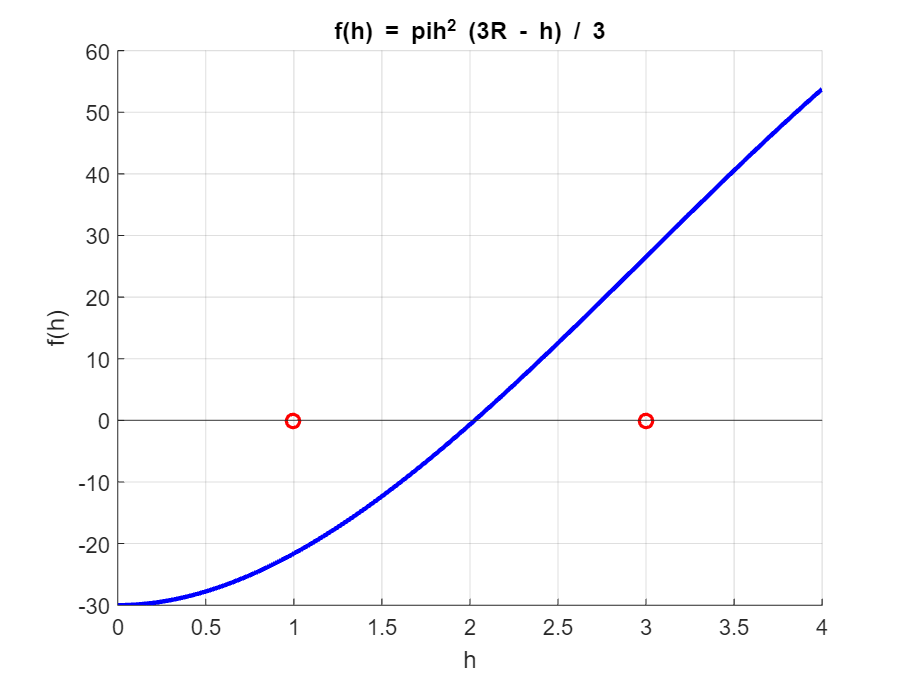

clc, clear, clf

R = 3; % radio del tanque en m 
V = 30; % volumen en m^3

f = @(h) pi .* h.^2 .* (( 3.*R - h) ./ 3) - V;
h = linspace(0, 4, 100);

% Gráfica
hold on 
yline(0)
xline(0)
fs = f(h);
plot(h, fs,'b', 'LineWidth', 2);
title('f(h) = pih^2 (3R - h) / 3')
xlabel('h')
ylabel('f(h)')
x_punto = [1, 3];
y_punto = [0,0];
plot(x_punto, y_punto, 'or', 'LineWidth', 1.5);

grid on 
hold off

**c) **

Observando la gráfica vemos dos raices. Sin embargo, por el contexto del problema la solución debe ser positiva, debido a que nos piden la altura del agua del depósito, por lo tanto nos quedamos con el intervalo:  [ 1 , 3 ].

a = 1;
b = 3; 
ermax = 10e-8; % error menos a 10e-6

[xs, k] = regulafalsi(f, a, b, ermax);

Unrecognized function or variable 'regulafalsi'.

fprintf("La altura del agua en el depósito es: %.4f m", xs)
fprintf("El método de regula falsi ha utilizado %d iteraciones", k)
Vs = pi * xs^2 * ((3*R - xs) / 3);
fprintf("Comprobación del volumen contenido en el depósito: %.6f m^3", Vs) 